# Navigate Global Path through Offroad Terrain Using Local Planner

In the previous two examples, you learned how to [process digital elevation data](matlab:open('./CreateRoutePlannerUsingDigitalElevationData.mlx')) to derive structure (i.e. road-networks) from terrain, and how to [create planners](matlab:open('./CreateTerrainAwareGlobalPlanners.mlx')) that generate collision-free paths through terrain where structure may not exist. In this example, you will develop a local planner capable of following the global reference paths created by the aforementioned tools while adhering to your vehicle's kinematic and geometric constraints.

## Develop Local Planner

Begin by loading the terrain and global paths generated in the previous examples, namely the digital elevation data from the first example, and the reference path and planner parameters generated in the second example:

% Load the digital elevation data generated in first example
load("OpenPitMinePart1Data.mat","dem","pathList");

% Load the reference path and planner parameters generated in second example
load("OpenPitMinePart2Data.mat","originalReferencePath","smoothedReferencePath","fixedTerrainAwareParams","tuneableTerrainAwareParams");

% Create costMaps from dem
[costMap,maxSlope] = exampleHelperDem2mapLayers(dem,tuneableTerrainAwareParams.MaxAngle,fixedTerrainAwareParams.Resolution);
obstacles = getLayer(costMap,"terrainObstacles");

### Define Parameters of Vehicle and Local Planner

The next step is to specify the parameters needed to represent the geometry and kinematic constraints of your vehicle. Similar to the terrain-aware planner in the previous example, you should consider separating these parameters into those than might change throughout the vehicle's operation, and those that will likely remain fixed. For the time being this is purely for organizational purposes, but in the final example you will integrate these different planning modules into a Simulink model, with fixed parameters being exposed through block masks, and tunable parameters passed as Simulink bus signals.

It is also worth noting here that the parameters of the local planner should be chosen with those of the global planner in mind. As an example, this could either mean keeping shared parameters like the `MinTurningRadius` identical in both planners, or possibly using a larger radius in the global planner, thereby ensuring that the local controller is able to follow the reference path effectively.

% Generate TEB controller parameters
[tunableTEBParams,fixedTEBParams] = exampleHelperTEBParams

tunableTEBParams = struct with fields:
           LookaheadTime: 6
    ObstacleSafetyMargin: 1
             CostWeights: [1×1 struct]
        MinTurningRadius: 17.2000
             MaxVelocity: [16 0.9302]
         MaxAcceleration: [0.6000 0.1000]
      MaxReverseVelocity: 8


fixedTEBParams = struct with fields:
                Length: 6.5000
                 Width: 5.7600
          NumIteration: 3
    ReferenceDeltaTime: 0.2000
      RobotInformation: [1×1 struct]


vehDims = exampleHelperVehicleGeometry(fixedTEBParams.Length,fixedTEBParams.Width,"collisionChecker");
collisionChecker = inflationCollisionChecker(vehDims,3);

To ensure our local planner is able to follow the paths in our road network, perform the same road-network inflation outlined in the second example:

exampleHelperInflateRoadNetwork(obstacles,pathList,collisionChecker.InflationRadius*1.5);

Lastly, create a local ego map which only covers the "reachable" region surrounding the vehicle. This minimizes the amount of computation `controllerTEB` requires for computing nearest obstacles, and also limits the size of the map signals you will need to pass between blocks in the upcoming Simulink models.

% Compute max distance traversible in an iteration of the local planner
maxDistance = (tunableTEBParams.MaxVelocity(1)*tunableTEBParams.LookaheadTime/obstacles.Resolution);

% Create the ego-centric local map
localMap = binaryOccupancyMap(2*maxDistance,2*maxDistance,obstacles.Resolution);
localMap.GridOriginInLocal = -localMap.GridSize/(2*localMap.Resolution);

### Construct Local Planner

With the parameters defined and path smoothed, the next step is to create a local planner and update its properties.

% Construct planner
teb = controllerTEB(smoothedReferencePath, localMap);

% Update parameters
teb.NumIteration            = fixedTEBParams.NumIteration;
teb.ReferenceDeltaTime      = fixedTEBParams.ReferenceDeltaTime;
teb.RobotInformation        = fixedTEBParams.RobotInformation;
teb.ObstacleSafetyMargin    = collisionChecker.InflationRadius*2;
teb.LookAheadTime           = tunableTEBParams.LookaheadTime; % In seconds
teb.CostWeights.Time        = tunableTEBParams.CostWeights.Time;
teb.CostWeights.Smoothness  = tunableTEBParams.CostWeights.Smoothness;
teb.CostWeights.Obstacle    = tunableTEBParams.CostWeights.Obstacle;
teb.MinTurningRadius        = tunableTEBParams.MinTurningRadius;
teb.MaxVelocity             = tunableTEBParams.MaxVelocity;
teb.MaxAcceleration         = tunableTEBParams.MaxAcceleration;
teb.MaxReverseVelocity      = tunableTEBParams.MaxReverseVelocity;

## Handling **controllerTEB** Exit Flags

When dealing with optimization-based tools, you may find that solvers are often plagued with local-minima and soft constraint violations, or they may fail to converge entirely.

Fortunately, [`controllerTEB`](https://www.mathworks.com/help/nav/ref/controllerteb.html) returns error codes which can help shed light on issues when they occur. Below we have identified several failure modes and post-failure countermeasures:

#### **ExitFlag 3**: Violation of the minimum turning radius by more than 10%

**Potential Behavior:** Control commands are returned, but the vehicle does not follow the local optimized path when the commands are applied.

**Potential Cause:** This flag is often encountered when the vehicle's orientation deviates from the nearby reference path. The optimizer wants to follow the path closely, which can sometimes overpower the constraints that try to keep the control commands kinematically feasible.

**Mitigation: **Capping control commands at their limits when the optimizer produces commands that violate the kinematics of the vehicle. This will produce a path that deviates from the optimal solution but can jog the vehicle out of the local minima.

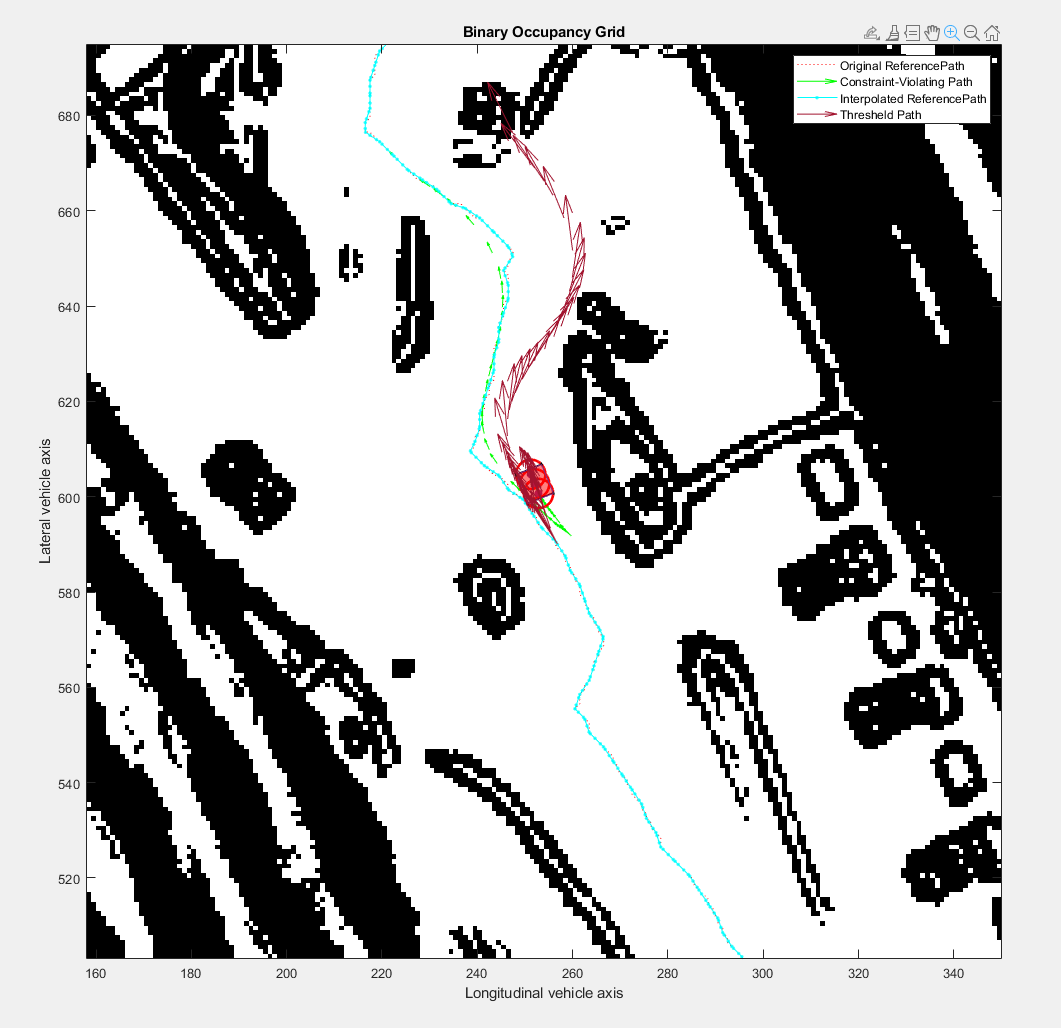

#### ExitFlag 2: Violation of the obstacle safety margin by more than 10%

**Potential Behavior:** The optimized path may contain collisions, or it might not.

**Potential Cause:** This flag can appear when the reference path moves through a tight corridor, or when the safety margin is large relative to the vehicle's actual dimensions.

**Mitigation Strategy:** The TEB's `ObstacleSafetyMargin` is, by definition, extra padding surrounding the vehicle dimensions. Therefore you should first double-check whether an obstacle-constraint violation actually results in collision, or just enters the padded region. In cases where the just the *padding* is in violation, your vehicle is not in collision, so you can choose to ignore the violation.

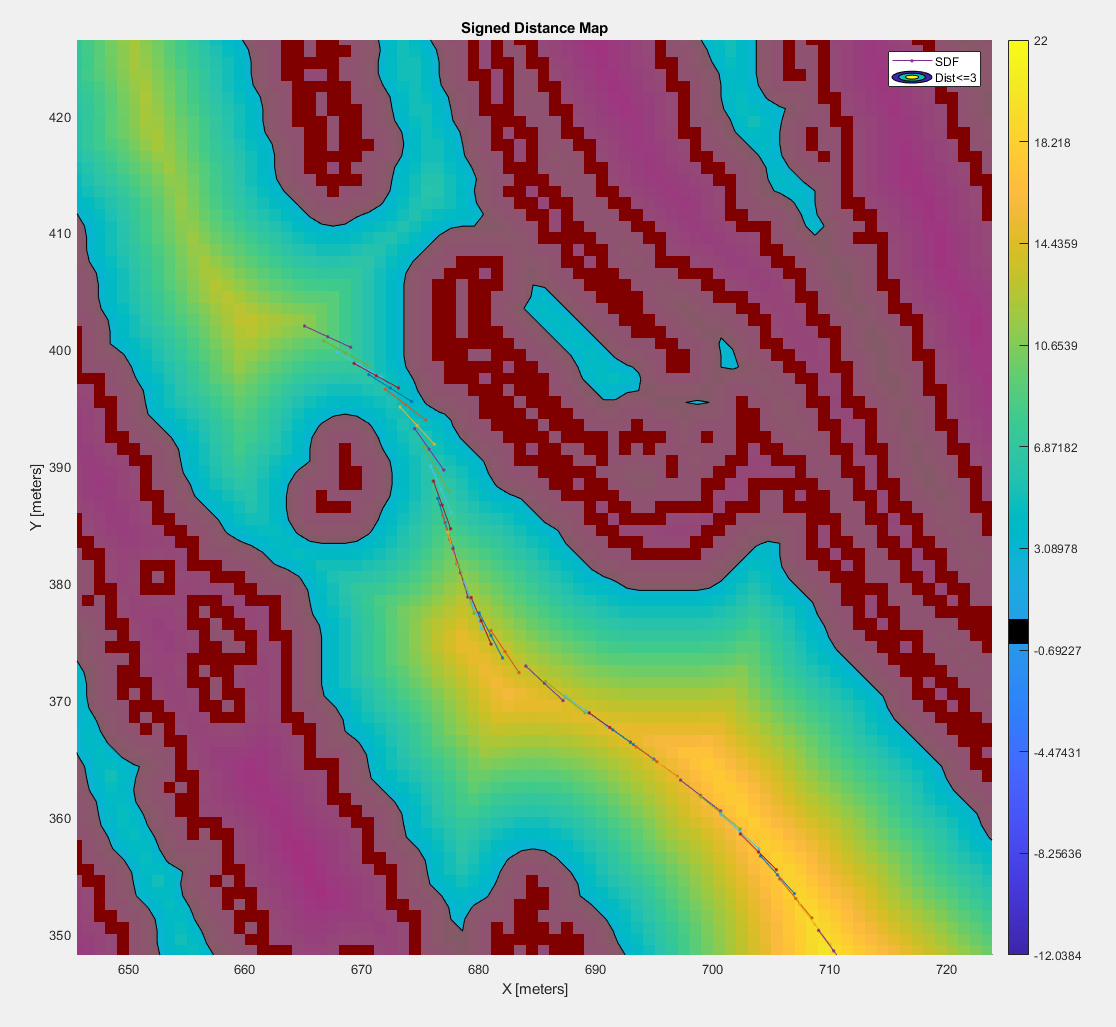

#### **No output or **`LastFeasibleIdx == 1`**:** May occur alongside any `ExitFlag`

**Potential Behavior:** Either the planner returns a set of commands with an immediate violation, or the output only contains a single command of `[0,0]`

**Potential Cause:** This might indicate an inescapable local minima, but for non-holonomic vehicles, it often indicates that the nearby points in the reference path are unreachable. This often occurs when a local replan is triggered while the vehicle is moving parallel to the reference path, or if the path changes direction rapidly.

**Mitigation Strategy:** As shown in the image below, the points in the reference path nearest to the vehicle lie inside the vehicle's `MinTurningRadius`, meaning the planner will be unable to reach them unless it violates the vehicle's kinematic constraints. To test for this condition, [`exampleHelperProcessTEBErrorCodes`](matlab:open('exampleHelperProcessTEBErrorCodes')) removes these unreachable points from the reference path and requests a local replan. If the local replan fails a second time, then the helper returns its own error code requesting that a global replan is performed.

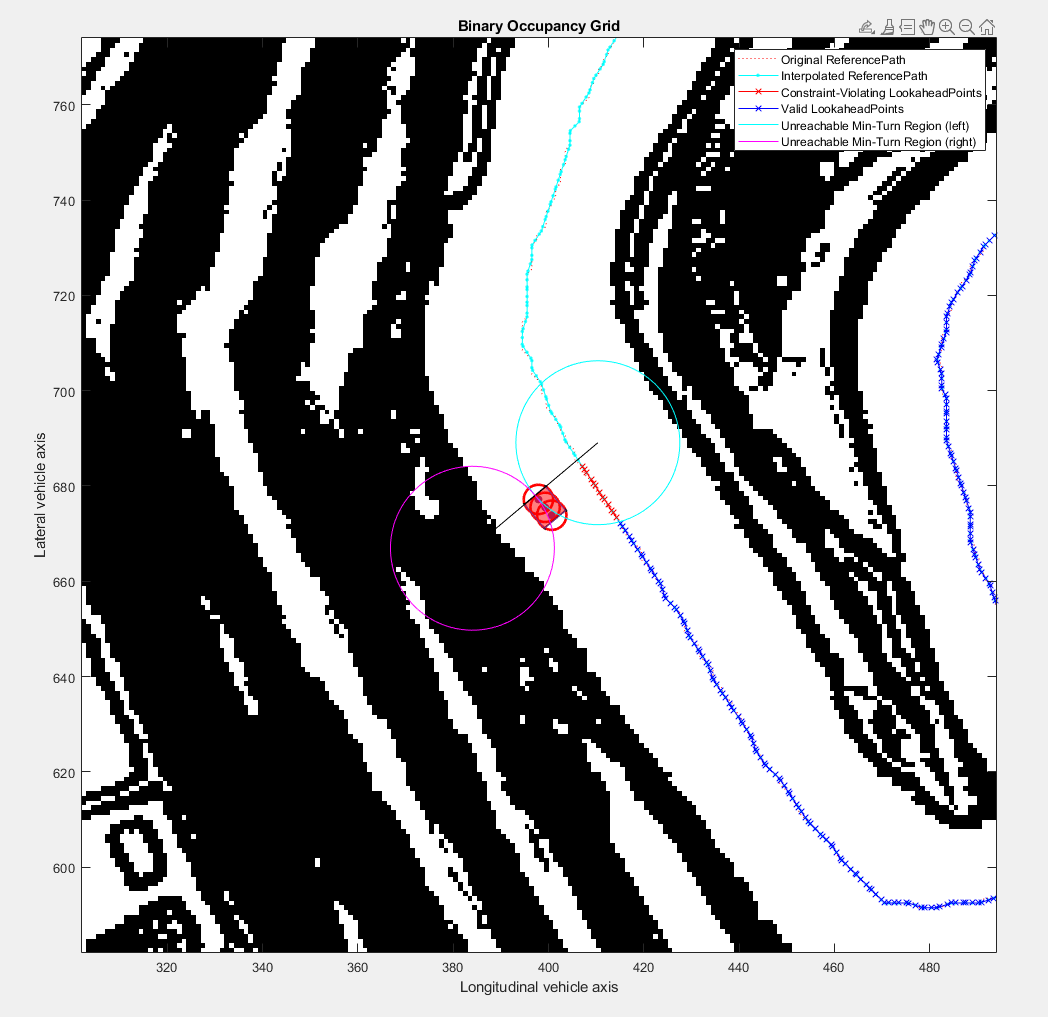

Note that the failure conditions above are not exhaustive, and the remedies above do not represent a complete solution. Rather, they demonstrate how one can use the TEB error codes to reason about and work around edge-cases caught while prototyping.

## Simulate Vehicle Following Reference Path

The following section will simulate a vehicle being driven by the `controllerTEB` outputs along the reference generated in the previous example. The local planner generates a time-stamped sequence of `[velocity,angularVelocity]` control commands which are then integrated to update the state of the vehicle.

### Set Up Simulation Parameters

First initialize some parameters needed to simulate the vehicle, such as the visualization interval, and integration step size:

%% Follow path and visualize
teb.ReferencePath = smoothedReferencePath;
curpose = smoothedReferencePath(1,:);
curvel = [0 0];
simtime = 0;
tsReplan = 3;
tsIntegrator = 0.001; % Reducing timestep can lead to more accurate path tracking
tsVisualize = 0.1;
itr = 0;
goalReached = false;
tVis = inf;
tPlan = inf;
adjustedPath = 0;

### Run Simulation

The simulation will continue until the vehicle either nears the end of the reference path, or a local minima is encountered which requires a new global path.

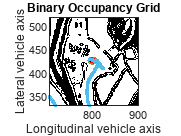

% Show the updated information which is input to or output from controllerTEB
figure
show(obstacles)
hold on
exampleHelperPlotLines(teb.ReferencePath,{"MarkerSize",10});
hTEBPath1_1 = quiver(nan,nan,nan,nan,.2,DisplayName="Current Path");
figure;
move(localMap,curpose(1:2),MoveType="Absolute");
syncWith(localMap,obstacles);
h = show(localMap);
ax2 = h.Parent;
hold on;
exampleHelperPose2Quiver(originalReferencePath,{"AutoScale","off"});
exampleHelperPose2Quiver(smoothedReferencePath,{"AutoScale","off"});
hRef = exampleHelperPlotLines(teb.ReferencePath,{"MarkerSize",10});
hTEBPath1_2 = quiver(nan,nan,nan,nan,.2,DisplayName="Current Path");
[~,hVeh] = exampleHelperCreateVehicleGraphic(gca,"Start",collisionChecker);
hTEBPath2_2 = hgtransform;
arrayfun(@(x)set(x,"Parent",hTEBPath2_2),hVeh);
hRefCur = exampleHelperPlotLines(teb.ReferencePath,".-");
while norm(curpose(1:2) - smoothedReferencePath(end,1:2),2) > 10
    % Update map to keep robot in center of the map. Also update
    % the map with new information from global map or measurement
    % from sensors.
    if tVis >= tsVisualize
        % Update local map/visualization
        move(localMap,curpose(1:2),"MoveType","Absolute","SyncWith",obstacles);
        show(localMap,Parent=ax2,FastUpdate=1);
        hTEBPath2_2.Matrix(1:3,:) = [eul2rotm([0 0 curpose(3)],'XYZ') [curpose(1:2)';0]];
        drawnow limitrate;
        tVis = 0;
    end

    if tPlan >= tsReplan
        % Update local map
        move(localMap,curpose(1:2),"MoveType","Absolute","SyncWith",obstacles);
        
        % Generate new vel commands with teb
        [velcmds,tstamps,curpath,info] = teb(curpose, curvel);
        
        if info.HasReachedGoal
            break;
        end
        
        % Show the updated information which is input to or output
        % from controllerTEB
        set(hTEBPath1_1,XData=curpath(:,1),YData=curpath(:,2), ...
               UData=cos(curpath(:,3)),VData=sin(curpath(:,3)));

        set(hTEBPath1_2,XData=curpath(:,1),YData=curpath(:,2), ...
               UData=cos(curpath(:,3)),VData=sin(curpath(:,3)));
        set(hRefCur,XData=teb.ReferencePath(:,1),YData=teb.ReferencePath(:,2));
        hTEBPath2_2.Matrix(1:3,:) = [eul2rotm([0 0 curpose(3)],'XYZ') [curpose(1:2)';0]];
        
        % Post-process the TEB results, handling error codes and constraint
        % violations.
        [velcmds,tstamps,curpath,adjustedPath,needLocalReplan,needFreeSpaceReplan] = ...
            exampleHelperProcessTEBErrorCodes(teb,curpose,curvel,velcmds,tstamps,curpath,info,adjustedPath, ...
            teb.RobotInformation.Dimension(1),teb.RobotInformation.Dimension(2));

        if needLocalReplan
            continue;
        else 
            if needFreeSpaceReplan
                error('Need replan');
            end
        end

        timestamps = tstamps + simtime;
        
        tVis = 0;
        tPlan = 0;
    end
    
    % Reset the adjustedPath flag whenever TEB is successful or results
    % can be corrected.
    adjustedPath = 0;

    % Integrate the model
    simtime = simtime + tsIntegrator;
    tVis = tVis + tsIntegrator;
    tPlan = tPlan+tsIntegrator;

    % Compute the instantaneous velocity to be sent to the robot
    % from the series of timestamped commands generated by
    % controllerTEB
    velcmd = velocityCommand(velcmds, timestamps, simtime);
    
    % Very basic robot model, should be replaced by simulator.
    statedot = [velcmd(1)*cos(curpose(3)) ...
                velcmd(1)*sin(curpose(3)) ...
                velcmd(2)];
    curpose = curpose + statedot * tsIntegrator;
    curvel = velcmd;
end

## Conclusion

In this example you developed a local path follower using `controllerTEB`. This subsystem took a reference path generated by the global planners in the second example and you used it to iteratively plan a sequence of control commands that moved the vehicle along the path while avoiding obstacles when integrated.

You also learned some of the common pitfalls that optimization-based planners may encounter, and developed strategies on how to debug and mitigate such issues inside `exampleHelperProcessTEBErrorCodes`. Lastly, you simulated the offroad vehicle and visualized the results.

In the [next and final example](matlab:open('./ModelAndControlAutonomousHaulTruck.mlx')) you will learn how to integrate all of these subsystems using Simulink and Stateflow. The integrated model will serve as the planning stack for an autonomous haul-truck in a copper mine.

*Copyright 2023 The MathWorks, Inc.*